# Graphic Filter Calculator

Use this Live Code Script to compute the values and outputs needed for the project. You will submit this file as part of your submission.

## Your Student Number:

clearvars
student_number = 2012345;

## Introduction

The purpose of this project is to build and test a Simulink model of a single stage peaking filter for a ten-stage graphic equalizer. 

Before you begin, you should read Mark Wickert's articles: *Signals and Systems Concepts Used to Design an Audio Graphic Equalizer* [1] and *How to Characterize the Peaking Filter for an Audio Graphic Equalizer* [2] from the [Engineering for Dummies](https://www.dummies.com/education/science/science-engineering/) resource.

The filter parameters that you will use will be computed based on your student number and will be unique to you. You *must* use these parameters in your design.

Once you have completed the calculations and answered the questions in this worksheet, you should build the filter in Simulink and test it using the methods similar to those shown in *Conduct Performance Testing on an Audio Graphic Equalizer *[3].

You should submit this worksheet and submit it with your claim and the simulink model with test setup by the deadline which is 4:00 pm on ....

## Set up

This code will output the centre frequency fc and gain setting GdB that you are to use in your design. 

Do not change the code in this section as I know what the results should be for you.

YOUR_ANSWER = 1; % dummy variable used as a place holder. Allows script to run without errors.

Replace `student_number` with your student number.

[fc,GdB] = personalize(student_number)

fc = 1000

GdB = 8

## The Project

You are to design a peaking filter that represents one stage of a ten-stage graphic equalizer.

A **peaking fliter** is designed to have a gain or loss (attenuation) in the range

$G_{\textrm{dB}} =\pm \;12$ dB at the centre frequency $f_c$ and should have unity gain ($G_\mathrm{dB} = 0$ dB) outside the active band. Thus the filter is a pass-band filter for $G_\mathrm{dB} > 0$ dB and a stop band filter for $G_\mathrm{dB} < 0$ dB.

The following questions allow you to explore one-stage of this filter and demonstrate your knowledge of filters and digital systems to do some ”back-of-the-envelope” calculations and provide some rough design sketches and calculations.

### (a) Centre frequencies

The centre frequencies of the graphic equalizer stages are given by the formula


$$f_{ci} = 31.25 \times 2^i\,\mathrm{Hz},\, i = 0,1,2,3,\ldots, 9.$$


and the range of the gain settings is continously variable in the range $$$-12\mathrm{dB} \le G_{\mathrm{dB}} \le 12\mathrm{dB}.$$$

i) Tabulate the centre frequencies that the graphic equalizer supports (`fci` should be a vector).

fci = YOUR_ANSWER

fci = 1

[2 marks]

ii) Compute the minimum loss (attenuation) and the maximum gain that must be achieved by the gain setting (that is convert $$G_{\mathrm{dB}$$ to $$G$$)

Gain

Gmax = YOUR_ANSWER

Gmax = 1

Gmin = YOUR_ANSWER

Gmin = 1

[4 marks]

## (b) Sampling properties

For your design, you are to assume that the sampling rate for your filter will be using a CD quality sampling rate of $$f_s=44.1$$ ksamples/s and a 16 bit Analogue to Digital Converter (ADC) per channel.

Your signal will be stereo signal. 

i) What data bit-rate will your hardware need to process? 

Sampling frequency $f_s$

fs = YOUR_ANSWER

fs = 1

Data rate

dr = YOUR_ANSWER % bits/s

dr = 1

[2 marks]

ii) What is the maximum frequency that your graphic equalizer can process? Comment on any limitations that this might impose on the highest-frequency filters in your graphic equalizer.

fmax = YOUR_ANSWER

fmax = 1

 Your comment

[2 marks]

iii) Compute the factor $$\hat{\omega}= 2\pi /f_s$$ rad/sample needed for the digital filter design coming up in (d).

wh = YOUR_ANSWER

wh = 1

[1 mark]

### (c) Filter properties

You will be designing your filter to have the centre frequency $f_c$ and gain $G_\mathrm{dB}}$ specified by your personalized data `fc` and `Gdb`. The response of such a filter is illutrated for the pass-band case is illustated in Figure 1. (The stop band would be this response mirrored around the frequency axis.)

A measure of a filter's quality is given by the $$Q$$-factor defined as

$ $Q = \frac{f_c}{f_2 - f_1}$,

where $$f_1$$ and $$f_2$$ are the frequencies at which the gain is 3 dB below the maximum for a pass-band filter (boost) or 3 dB above the minimum for a stop-band filter (cut). (Note: $$\Delta f = f_2 - f_1$$ defines the  bandwidth of the filter and is inversely proportional to $$Q$$.)

   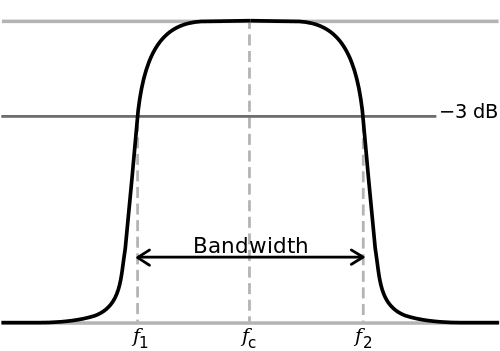 

**Figure 1** -- A bandpass filter's bandwidth. Source Henrikb4 at en.wikipedia, CC BY 2.5, [https://commons.wikimedia.org/w/index.php?curid=2256114.](https://commons.wikimedia.org/w/index.php?curid=2256114)

For a filter with a bandwidth of one actave $$f_2 = 2f_1$$.

Given that $$f_c = \sqrt{f_1 f_2}$$:

i) Compute the values of the cut-off frequencies $$f_1$$ and $$f_2$$ in Hz for your personlized value of $f_c$. Explain your answers.

f1 = YOUR_ANSWER

f1 = 1

f2 = YOUR_ANSWER

f2 = 1

[2 marks]

ii) Compute the value of $$Q$$ achieved. 

Q = YOUR_ANSWER

Q = 1

[2 marks]

iii) Sketch the frequency response you would expect to see for your filter. (insert the sketch as an image)

[3 marks]

## (d) The Design

A digital Infinite Impulse Response (IIR) filter that implements the peaking filter has transfer function:


$$$$H_{\mathrm{pk}}(z) = \frac{Y(z)}{X(z)} = C_{\mathrm{pk}}\left(\frac{1+b_1z^{-1}+b_2z^{-2}}{1 + a_1z^{-1} + a_2z^{-1}}\right)$$$$


i) Build the block diagram for this filter in Simulink and insert a screen shot here. The structure should be based on the block diagram [Models of Discrete-Time Systems — EG-247 Signals and Systems (cpjobling.github.io)](https://cpjobling.github.io/eg-247-textbook/dt_systems/4/dt_models.html#block-diagram-of-the-digital-bw-filter) [see: [digifilter.slx](https://cpjobling.github.io/eg-247-textbook/dt_systems/4/matlab/digifilter.slx)]

[5 marks]

 ii) The design parameters $$\mu$$ and  are needed to compute the filter coefficients $$C_{\mathrm{pk}}$, $b_1$, $b_2$, $a_1$ and $a_2$. $Use the equations

 for 


$$\mu = 10^{\left(G_\mathrm{dB}/20\right)}$$


and 


$$k_q = \left(\frac{4}{1+\mu}\right)\tan\left(\frac{\hat{\omega}_c}{2Q}\right)$$


to compute these values for your filter design.   

mu = YOUR_ANSWER

mu = 1

wch = YOUR_ANSWER

wch = 1

kq = YOUR_ANSWER

kq = 1

[2 marks]

iii) The peaking filter coefficients are given by the equations below.


$$c_{\mathrm{pk}} = \left(\frac{1+k_q\mu}{1+k_q}\right) $$



$$b_1 = \left(\frac{-2\cos(\hat{\omega}_c)}{1+k_q\mu}\right)$$



$$b_2 = \left(\frac{1-k_q\mu}{1+k_q\mu}\right)$$



$$a_1 = \left(\frac{-2\cos(\hat{\omega}_c)}{1+k_q}\right) $$



$$a_2 = \left(\frac{1-k_q}{1+k_q}\right)$$


Complete your design by computing the filter coefficients that correspond to your personalized filter settings.

### Filter Coefficients

cpk = YOUR_ANSWER

cpk = 1


b1 = YOUR_ANSWER

b1 = 1


b2 = YOUR_ANSWER

b2 = 1


a1 = YOUR_ANSWER

a1 = 1


a2 = YOUR_ANSWER

a2 = 1

[2 marks]

### Results

This will validate your design.

z = tf('z',1/fs)

z =
 
  z
 
Sample time: 1 seconds
Discrete-time transfer function.



Hz = tf(cpk*(z^2 + b1*z + b2)/(z^2 + a1*z + a2))

Hz =
 
  z^2 + z + 1
  -----------
  z^2 + z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.



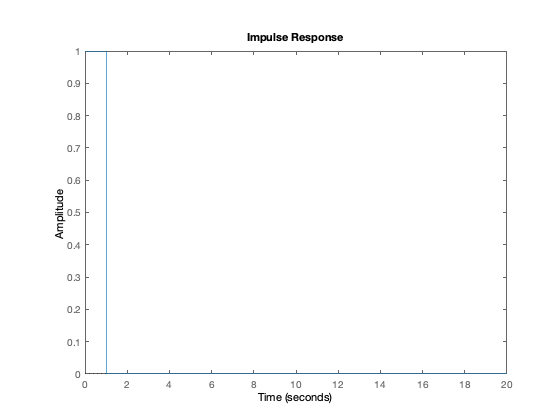

impulse(Hz)

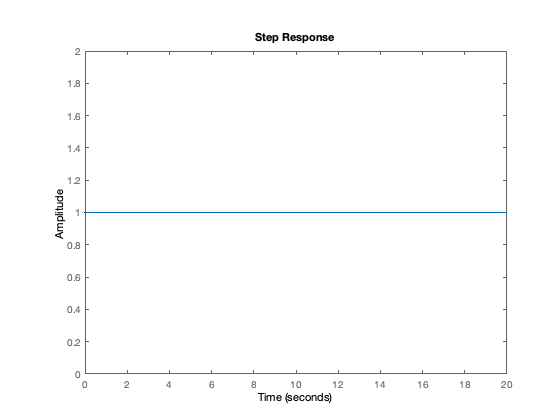

step(Hz)

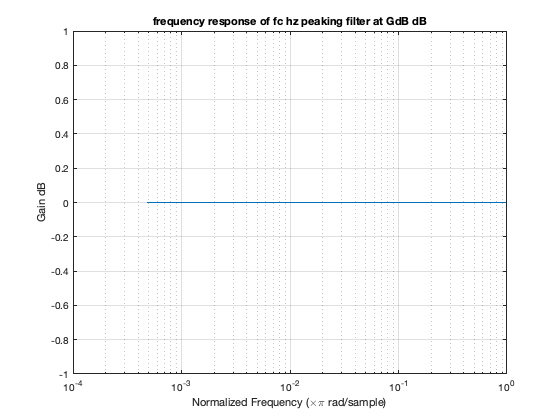

b = [cpk cpk*b1 cpk*b2];
a = [1 a1 a2];
[h,w] = freqz(b,a,2048);

semilogx(w/pi,20*log10(abs(h)))
grid
title('frequency response of fc hz peaking filter at GdB dB');
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Gain dB')

### Total Marks

There are 25 marks for completing this script. What will your claim be?

## Submission

See the [Project Description](https://cpjobling.github.io/eg-247-textbook/labs/project/index) for details of how to submit your project for assessment.

## Optional Next Steps

### Build a 10-band Graphic Equalizer with your friends

Get together with other members of the class and construct a Simulink model of a ten-stage graphic equalizer. Try running it with some audio files. Use the provided example test scripts `Three_Band_EQ` and `Three_Band_EQ_Model` as your starting point for these developments.

### MATLAB Audio Toolbox

The [MATLAB Audio Toolbox](https://uk.mathworks.com/help/audio/) provides tools for designing and exploring audio processing systems and icludes support for exploring and designing [graphic equalizers](https://uk.mathworks.com/help/audio/ug/graphic-equalization.html#responsive_offcanvas) [6]. View the online documentation on Graphic Equalizers. Add notes of any features that you find particularly interesting.

## References

[1] Wickert, Mark. Signals and Systems Concepts Used to Design an Audio Graphic Equalizer. Engineering for Dummies. Dummies.com. Online at: [https://www.dummies.com/education/science/science-engineering/11-signals-and-systems-concepts-used-to-design-an-audio-graphic-equalizer/.](https://www.dummies.com/education/science/science-engineering/11-signals-and-systems-concepts-used-to-design-an-audio-graphic-equalizer/.) Accessed on: 6th March 2021.

[2] Wickert, Mark. How to Characterize the Peaking Filter for an Audio Graphic Equalizer. Engineering for Dummies. Dummies.com. Online at: [https://www.dummies.com/education/science/science-engineering/how-to-characterize-the-peaking-filter-for-an-audio-graphic-equalizer/](https://www.dummies.com/education/science/science-engineering/how-to-characterize-the-peaking-filter-for-an-audio-graphic-equalizer/) Accessed on: 6th March 2021.

[3] Wickert, Mark. Conduct Performance Testing on an Audio Graphic Equalizer. Engineering for Dummies. Dummies.com. [https://www.dummies.com/education/science/science-engineering/conduct-performance-testing-on-an-audio-graphic-equalizer/](https://www.dummies.com/education/science/science-engineering/conduct-performance-testing-on-an-audio-graphic-equalizer/)

[4] Wickert, Mark. Signals and Systems Cheatsheet. Engineering for Dummies. Dummies.com. Online at: [https://www.dummies.com/education/science/signals-systems-for-dummies-cheat-sheet/.](https://www.dummies.com/education/science/signals-systems-for-dummies-cheat-sheet/.) Accessed on: 6th March 2021.

[5] Wickert, Mark. Signals and Systems for Dummies.1st Edition. 2013. For Dummies. Wiley, Hoboken NJ, USA. 2013. Online at: [https://whel-primo.hosted.exlibrisgroup.com/permalink/f/1pk86k3/44WHELF_SWA_ALMA_DS5177422270002417.](https://whel-primo.hosted.exlibrisgroup.com/permalink/f/1pk86k3/44WHELF_SWA_ALMA_DS5177422270002417.) Accessed 6th March 2021.

[6] Graphic Equalization. The Mathworks, MATLAB Audio Toolbox, Version 2020b. Online at: [https://uk.mathworks.com/help/audio/ug/graphic-equalization.html.](https://uk.mathworks.com/help/audio/ug/graphic-equalization.html.) Accessed 6th March 2021.